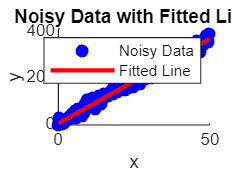

% Set random seed for reproducibility
clear all
close all
clc

rng(1);


% Parameters
a0 = -2.923;   % True intercept
b0 = 7.18;     % True slope
c0 = 1;        % True exp
mu = 0;        % Mean of noise
sigma = 3.8;   % Standard deviation of noise
N = 100;       % Number of data points
x_max = 50;    % Upper limit of x

% Generate x values uniformly in the range [0, 50]
x = linspace(0, x_max, N)';  % Nx1 column vector

% Generate noise from normal distribution N(mu, sigma^2)
e = normrnd(mu, sigma^2, N, 1);  % Nx1 column vector

% Generate the noisy y values
y1 = a0 + b0 * x + e;

% Fit the linear model to estimate the parameters using least squares
X = [ones(N, 1), x];  % Design matrix: [1 x]
theta_est = (X' * X) \ (X' * y1);  % Least squares estimate
a_est = theta_est(1);  % Estimated intercept
b_est = theta_est(2);  % Estimated slope


% Plot the noisy data and the fitted line
figure;
scatter(x, y1, 'b', 'filled');  % Plot noisy data points
hold on;
y_fit1 = a_est + b_est * x;  % Fitted line
plot(x, y_fit1, 'r-', 'LineWidth', 2);  % Plot fitted line

% Add labels and legend
xlabel('x');
ylabel('y');
title('Noisy Data with Fitted Line');
legend('Noisy Data', 'Fitted Line');


% Display estimated parameters
disp(['Estimated intercept: ', num2str(a_est)]);

Estimated intercept: -5.0678


disp(['Estimated slope: ', num2str(b_est)]);

Estimated slope: 7.2378



e1 =(1/N)*sum((y1-y_fit1).^2)

e1 = 203.7023

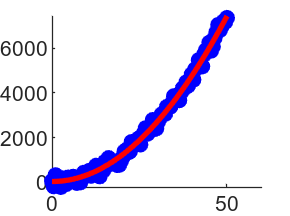


% Parameters
a0 = -2.923;   % True intercept
b0 = 7.18;     % True slope
c0 = 2.8;      % True exp
mu = 0;        % Mean of noise
sigma = 12.8;  % Standard deviation of noise
N = 100;       % Number of data points
x_max = 50;    % Upper limit of x

% Generate x values uniformly in the range [0, 50]
x = linspace(0, x_max, N)';  % Nx1 column vector

% Generate noise from normal distribution N(mu, sigma^2)
e = normrnd(mu, sigma^2, N, 1);  % Nx1 column vector

% Generate the noisy y values
y2 = a0 + b0 * x + c0*x.^2 + e;

% Fit the linear model to estimate the parameters using least squares
X = [ones(N, 1), x, x.^2];  % Design matrix: [1 x]
theta_est = (X' * X) \ (X' * y2);  % Least squares estimate
a_est = theta_est(1);  % Estimated intercept
b_est = theta_est(2);  % Estimated slope
c_est = theta_est(3);  % Estimated slope

% Plot the noisy data and the fitted line
figure(2);
scatter(x, y2, 'b', 'filled');  % Plot noisy data points
hold on;
y_fit2 = a_est + b_est * x + c_est*x.^2;  % Fitted line
plot(x, y_fit2, 'r-', 'LineWidth', 2);  % Plot fitted line
hold off

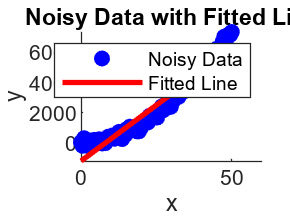


% Fit the linear model to estimate the parameters using least squares
X = [ones(N, 1), x];  % Design matrix: [1 x]
theta_est = (X' * X) \ (X' * y2);  % Least squares estimate
a_est = theta_est(1);  % Estimated intercept
b_est = theta_est(2);  % Estimated slope

figure(3)
scatter(x, y2, 'b', 'filled');  % Plot noisy data points
hold on
y_fit3 = a_est + b_est * x;  % Fitted line
plot(x, y_fit3, 'r-', 'LineWidth', 2);  % Plot straight line
hold off

% Add labels and legend
xlabel('x');
ylabel('y');
title('Noisy Data with Fitted Line');
legend('Noisy Data', 'Fitted Line');


% Display estimated parameters
disp(['Estimated intercept: ', num2str(a_est)]);

Estimated intercept: -1183.0196


disp(['Estimated slope: ', num2str(b_est)]);

Estimated slope: 147.9386


disp(['Estimated quadratic coefficient: ', num2str(c_est)]);

Estimated quadratic coefficient: 2.9637




e2 =(1/N)*sum((y2-y_fit2).^2)

e2 = 2.4807e+04

e3 =(1/N)*sum((y2-y_fit3).^2)

e3 = 3.4215e+05

## Part 2 1c)

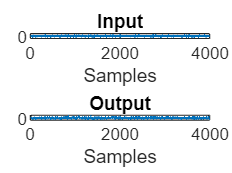

clear all
close all
clc

% To find the predictor of ARMAX, iterative search is needed, for example
% the newton method.

input=load('input.mat');
output=load('output.mat');

u=input.u;
y=output.y;

% Let's plot the data (1 output realization)
figure(1); clf;
subplot(2,1,1)
plot(u)
title('Input')
xlabel('Samples')
subplot(2,1,2)
plot(y)
hold on
title('Output')
xlabel('Samples')


N=length(u);

% Identification using Least-Squares formula and prediction

% Now we do some identification!
% First of all let's split the data in estimation and validation sets
% (half and half)
uest = u(1:N/2);
yest = y(1:N/2);
uval = u(N/2+1:end);
yval = y(N/2+1:end);
% Let's now use the model we found to predict the output!
% Using validation data (or estimation data, just for a check)

NN = N/2;
% Let's redefine the data variables so it will be easy to switch from
% validation to estimation sets.
%yn = yval;
%un = uval;
yn = yest; 
un  = uest;

% Now that we have the predictor in the y(t) = phi(t)*Theta form, we can
% derive the vector form as well: Y = H*Theta, where, now Y is a vector and
% H is matrix.

% Let's build the matrices H_12_i:


H_12a = zeros(N/2,3);
H_12a(1,:) = [0 0 0]; % Initial value
for i=2:N/2
    H_12a(i,1) = [yest(i-1)];
end

for i=3:N/2
    H_12a(i,2) = [yest(i-2)];
end
H_12a(:,3) = uest;

H_12b = zeros(N/2,4);
H_12b(1,:) = [0 0 0 0]; % Initial value

for i=2:N/2
    H_12b(i,1) = [yest(i-1)];
end

for i=3:N/2
    H_12b(i,2) = [yest(i-2)];
end

for i=2:N/2
    H_12b(i,4) = [uest(i-1)];
end

H_12b(:,3) = uest;


H_12c = zeros(N/2,4);
H_12c(1,:) = [0 0 0 0]; % Initial value
for i=2:N/2
    H_12c(i,1) = [yest(i-1)];
end

for i=3:N/2
    H_12c(i,2) = [yest(i-2)];
end

for i=4:N/2
    H_12c(i,3) = [yest(i-3)];
end

for i=2:N/2
    H_12c(i,4) = [uest(i-1)];
end



theta_a = (H_12a'*H_12a)\(H_12a'*yest);
theta_b = (H_12b'*H_12b)\(H_12b'*yest);
theta_c = (H_12c'*H_12c)\(H_12c'*yest);

% theta should be be a vector with two elements, estimated value for a and
% estimate value for b. Let's pick this two elements separetely:
theta_A = [theta_a(1),theta_a(2),theta_a(3)] % a1 a2 b0

theta_A =     0.9590   -0.3567    0.0688



theta_B = [theta_b(1),theta_b(2),theta_b(3),theta_b(4)] % a1 a2 b0 b1

theta_B =     0.8923   -0.3116    0.0113    0.9946



theta_C = [theta_b(1),theta_b(2),theta_b(3),theta_b(4)] % a1 a2 a3 b1

theta_C =     0.8923   -0.3116    0.0113    0.9946


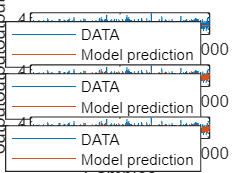


% Let's do prediction first, write your code for 1-step-ahead predictor
ypred = zeros(NN,1); % that's the vector where we will store the predicted output
ypred(1) = yn(1); % initial output is known
% ypred(2) = yn(2)

for t=3 : NN
    ypred_12a(t) =  -theta_A(1)*ypred(t-1) - theta_A(2)*ypred(t-2) + theta_A(3)*un(t);
end

for t = 3:NN
    ypred_12b(t) =  -theta_B(1)*ypred(t-1) - theta_B(2)*ypred(t-2) + theta_B(3)*un(t) + theta_B(4)*un(t-1);
end
% ypred(3) = yn(3);

for t=4:NN
     ypred_12c(t) =  -theta_C(1)*ypred(t-1) - theta_C(2)*ypred(t-2) - theta_C(3) * ypred(t-3) + theta_C(4)*un(t-1);
end

% Once we have the predicted output we can compute the least-squares error with the true data
predERRORa = yn'-ypred_12a;
predERRORb = yn'-ypred_12b;
predERRORc = yn'-ypred_12c;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Write your code here %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
predRMSEa = rms(predERRORa);
predRMSEb  = rms(predERRORb);
predRMSEc  = rms(predERRORc);
    
% plot DATA vs MODEL prediction
figure(2); clf;
subplot(3,1,1)
plot(yn)
hold on
plot(ypred_12a)
legend('DATA','Model prediction')
xlabel('Samples')
ylabel('output')
hold off
subplot(3,1,2)
plot(yn)
hold on
plot(ypred_12b)
legend('DATA','Model prediction')
xlabel('Samples')
ylabel('output')
hold off
subplot(3,1,3)
plot(yn)
hold on
plot(ypred_12c)
legend('DATA','Model prediction')
xlabel('Samples')
ylabel('output')

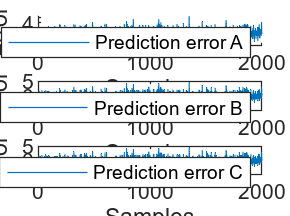


figure(3), clf;
subplot(3,1,1)
hold on
plot(predERRORa)
legend('Prediction error A')
xlabel('Samples')
ylabel('error')
subplot(3,1,2)
hold off
plot(predERRORb)
hold on
legend('Prediction error B')
xlabel('Samples')
ylabel('error')
subplot(3,1,3)
hold off
plot(predERRORc)
hold on
legend('Prediction error C')
xlabel('Samples')
ylabel('error')



disp(['Prediction RMS error for 12A is: ' num2str(predRMSEa)])

Prediction RMS error for 12A is: 1.5567


disp(['Prediction RMS error for 12B is: ' num2str(predRMSEb)])

Prediction RMS error for 12B is: 1.1449


disp(['Prediction RMS error for 12C is: ' num2str(predRMSEc)])

Prediction RMS error for 12C is: 1.1451
